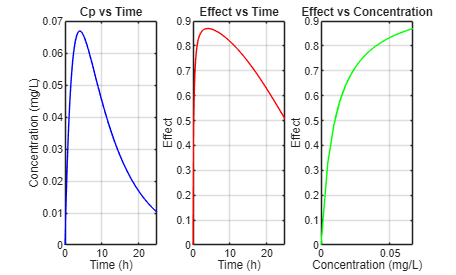


Emax = 1;
EC50 = 0.01;   % mg/L

E = (Emax * Cp) ./ (EC50 + Cp);   % direct effect model

% Three separate plots
figure()
subplot(1,3,1), plot(t, Cp, 'b-');
xlabel('Time (h)');
ylabel('Concentration (mg/L)');
title('Cp vs Time');
grid on

subplot(1,3,2), plot(t, E, 'r-');
xlabel('Time (h)'); 
ylabel('Effect');
title('Effect vs Time');
grid on

subplot(1,3,3), plot(Cp, E, 'g-');
xlabel('Concentration (mg/L)'); 
ylabel('Effect');
title('Effect vs Concentration');
grid on

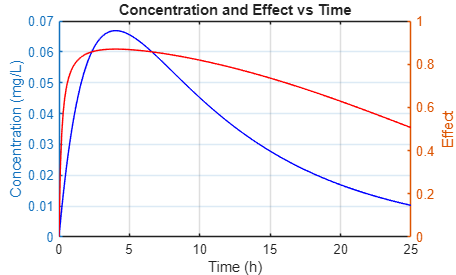

% Combined plot with two y‑axes
figure()
yyaxis left
plot(t, Cp, 'b-');
ylabel('Concentration (mg/L)');

yyaxis right
plot(t, E, 'r-');
ylabel('Effect');
xlabel('Time (h)');
title('Concentration and Effect vs Time');
grid on;